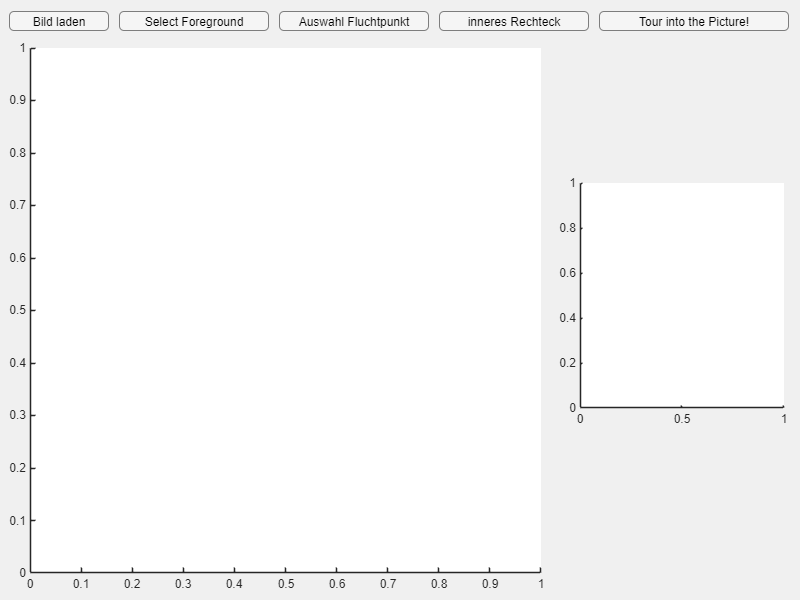

clc;
clearvars;

%------------------------------- Change log --------------------------------------
% 'BackgroundAxes': Background display zone
% 'ForegroundAxes': foreground display zone
% 'Image': Background
% 'ForegroundImage': Foreground objects

tip_gui;

function tip_gui
    % Create a figure for the GUI
    fig = uifigure('Name', 'Tour Into the Picture', 'Position', [100, 100, 800, 600]);

    % Load image button
    uibutton(fig, 'Position', [10, 570, 100, 20], 'Text', 'Bild laden', 'ButtonPushedFcn', @(btn, event) loadImage(fig));
    
    % Extruct foreground objects
    uibutton(fig, 'Position', [120, 570, 150, 20], 'Text', 'Select Foreground', 'ButtonPushedFcn', @(btn, event) selectForeground(fig));
    
    % Select vanishing point button
    uibutton(fig, 'Position', [280, 570, 150, 20], 'Text', 'Auswahl Fluchtpunkt', 'ButtonPushedFcn', @(btn, event) selectVanishingPoint(fig));

    % Draw inner rectangle button
    uibutton(fig, 'Position', [440, 570, 150, 20], 'Text', 'inneres Rechteck', 'ButtonPushedFcn', @(btn, event) drawInnerRectangle(fig));
    
    % Start animation button (bottom right corner)
    uibutton(fig, 'Position', [600, 570, 190, 20], 'Text', 'Tour into the Picture!', 'ButtonPushedFcn', @(btn, event) startAnimation(fig));

    % Axes for displaying the image and animation
    axBackground = uiaxes(fig, 'Position', [10, 10, 540, 550]); % Adjusted size to accommodate the button
    setappdata(fig, 'BackgroundAxes', axBackground);

    % Axes for displaying the foreground image
    axForeground = uiaxes(fig, 'Position', [560, 175, 230, 250]);
    setappdata(fig, 'ForegroundAxes', axForeground);

    % Initialize data
    setappdata(fig, 'Image', []);
    setappdata(fig, 'VanishingPoint', []);
    setappdata(fig, 'InnerRectangle', []);
    setappdata(fig, 'VanishingPointHandle', []); % Store handle for vanishing point
    setappdata(fig, 'MeshLines', []); % Store handles for mesh lines
    setappdata(fig, 'RectangleHandle', []); % Store handle for inner rectangle
end

function loadImage(fig)
    [file, path] = uigetfile({'*.jpg;*.png'}, 'Select an Image');
    if isequal(file, 0)
        return;
    end
    img = imread(fullfile(path, file));
    setappdata(fig, 'Image', img);
    axBackground = getappdata(fig, 'BackgroundAxes');
    imshow(img, 'Parent', axBackground);
    % Adjust the axis properties to fit the image
    axis(axBackground, 'image');
    axBackground.XTick = [];
    axBackground.YTick = [];
end

function selectForeground(fig)
    axBackground = getappdata(fig, 'BackgroundAxes');
    axForeground = getappdata(fig, 'ForegroundAxes');
    img = getappdata(fig, 'Image');
    masks = getappdata(fig, 'Masks');

    if isempty(img)
        uialert(fig, 'Load an image first!', 'Image Not Found');
        return;
    end

    % Initialize with the original image
    compositeBackground = img;
    % Initialize the foreground image as fully transparent (all zeros)
    foregroundImage = zeros(size(img), 'like', img);
    
    finished = false;
    while ~finished
        h = drawpolygon('Parent', axBackground, 'Color', 'b');

        % Wait for user confirmation
        wait(h);
        
        if isvalid(h)
            % Create mask from polygon
            mask = createMask(h, img);
            masks{end+1} = mask;

            % Update composite foreground image
            currentForeground = img;
            currentForeground(repmat(~mask, [1, 1, 3])) = 0;
            foregroundImage = max(foregroundImage, currentForeground);

            % Update background
            for k = 1:3  % Apply regionfill to each channel
                compositeBackground(:,:,k) = regionfill(compositeBackground(:,:,k), mask);
            end

            % Display updated foreground and background
            imshow(foregroundImage, 'Parent', axForeground);
            imshow(compositeBackground, 'Parent', axBackground);
        else
            uialert(fig, 'Polygon was deleted or is invalid.', 'Error');
        end

        % Ask user if they want to add another foreground
        choice = uiconfirm(fig, 'Do you want to add another foreground?', 'Add Foreground', ...
                           'Options', {'Yes', 'No'}, 'DefaultOption', 2, 'CancelOption', 2);
        finished = strcmp(choice, 'No');
    end

    % Store the updated images and masks
    setappdata(fig, 'Image', compositeBackground);
    setappdata(fig, 'Masks', masks);
    setappdata(fig, 'ForegroundImage', foregroundImage);
end

function selectVanishingPoint(fig)
    img = getappdata(fig, 'Image');
    if isempty(img)
        uialert(fig, 'Please load an image first.', 'Error');
        return;
    end
    ax = getappdata(fig, 'BackgroundAxes');
    title(ax, 'Select the Vanishing Point');

    % Set the WindowButtonDownFcn for the figure
    fig.WindowButtonDownFcn = @(src, event) getVanishingPoint(src, event, fig);
end

function getVanishingPoint(~, ~, fig)
    ax = getappdata(fig, 'BackgroundAxes');
    cp = ax.CurrentPoint;
    x = cp(1, 1);
    y = cp(1, 2);

    % Get the axes limits
    xLimits = ax.XLim;
    yLimits = ax.YLim;

    % Check if the click was within the axes limits
    if x >= xLimits(1) && x <= xLimits(2) && y >= yLimits(1) && y <= yLimits(2)
        % Remove old vanishing point and mesh lines if they exist
        oldVpHandle = getappdata(fig, 'VanishingPointHandle');
        if ~isempty(oldVpHandle)
            delete(oldVpHandle);
        end

        oldMeshLines = getappdata(fig, 'MeshLines');
        if ~isempty(oldMeshLines)
            delete(oldMeshLines);
        end

        % Set the new vanishing point
        setappdata(fig, 'VanishingPoint', [x, y]);
        
        hold(ax, 'on');
        vpHandle = plot(ax, x, y, 'wo', 'MarkerSize', 10, 'LineWidth', 2); % Changed to white
        setappdata(fig, 'VanishingPointHandle', vpHandle);
        
        drawMeshLines(fig); % Update the mesh lines based on the new vanishing point
        
        hold(ax, 'off');
        title(ax, '');
        fig.WindowButtonDownFcn = ''; % Reset the WindowButtonDownFcn
    end
end

function drawInnerRectangle(fig)
    img = getappdata(fig, 'Image');
    if isempty(img)
        uialert(fig, 'Please load an image first.', 'Error');
        return;
    end
    ax = getappdata(fig, 'BackgroundAxes');
    title(ax, 'Draw the Inner Rectangle');

    % Set the WindowButtonMotionFcn for the figure to draw the rectangle immediately
    fig.WindowButtonDownFcn = @(src, event) startRectangleDraw(src, event, fig);
end

function startRectangleDraw(~, ~, fig)
    ax = getappdata(fig, 'BackgroundAxes');
    
    % Remove old rectangle if it exists
    oldRectHandle = getappdata(fig, 'RectangleHandle');
    if ~isempty(oldRectHandle)
        delete(oldRectHandle);
    end

    % Use drawrectangle to immediately start the drawing process
    rect = drawrectangle(ax, 'Color', 'g', 'LineWidth', 2);
    rect.addlistener('ROIMoved', @(src, event) updateRectangle(fig, rect.Position));
    setappdata(fig, 'InnerRectangle', rect.Position);
    setappdata(fig, 'RectangleHandle', rect);

    drawMeshLines(fig); % Update the mesh lines based on the new rectangle

    title(ax, '');
    fig.WindowButtonDownFcn = ''; % Reset the WindowButtonDownFcn
end

function updateRectangle(fig, position)
    setappdata(fig, 'InnerRectangle', position);
    drawMeshLines(fig); % Update the mesh lines when the rectangle is moved
end

function drawMeshLines(fig)
    ax = getappdata(fig, 'BackgroundAxes');
    vanishingPoint = getappdata(fig, 'VanishingPoint');
    innerRectangle = getappdata(fig, 'InnerRectangle');

    if isempty(vanishingPoint) || isempty(innerRectangle)
        return;
    end

    % Remove old mesh lines if they exist
    oldMeshLines = getappdata(fig, 'MeshLines');
    if ~isempty(oldMeshLines)
        delete(oldMeshLines);
    end

    hold(ax, 'on');
    % Define corners of the inner rectangle
    rect_x = innerRectangle(1);
    rect_y = innerRectangle(2);
    rect_w = innerRectangle(3);
    rect_h = innerRectangle(4);
    corners = [
        rect_x, rect_y;
        rect_x + rect_w, rect_y;
        rect_x + rect_w, rect_y + rect_h;
        rect_x, rect_y + rect_h
    ];

    % Get the image size
    img = getappdata(fig, 'Image');
    [imgHeight, imgWidth, ~] = size(img);

    % Calculate the intersections of the lines from the vanishing point through the corners of the rectangle
    % with the image boundaries
    vp_x = vanishingPoint(1);
    vp_y = vanishingPoint(2);
    meshLines = gobjects(size(corners, 1), 1);

    for i = 1:size(corners, 1)
        [x_inter, y_inter] = getBoundaryIntersections(vp_x, vp_y, corners(i, 1), corners(i, 2), imgWidth, imgHeight);
        meshLines(i) = plot(ax, [vp_x, x_inter], [vp_y, y_inter], 'w-', 'LineWidth', 0.5); % Changed to white
    end

    setappdata(fig, 'MeshLines', meshLines);
    hold(ax, 'off');
end

function [x_inter, y_inter] = getBoundaryIntersections(vp_x, vp_y, corner_x, corner_y, imgWidth, imgHeight)
    % Calculate the slope of the line from the vanishing point to the corner
    slope = (corner_y - vp_y) / (corner_x - vp_x);

    % Calculate the intersection points with the image boundaries
    if corner_x > vp_x
        % Right boundary
        x_inter = imgWidth;
        y_inter = vp_y + slope * (imgWidth - vp_x);
    else
        % Left boundary
        x_inter = 1;
        y_inter = vp_y + slope * (1 - vp_x);
    end

    if y_inter > imgHeight
        % Bottom boundary
        y_inter = imgHeight;
        x_inter = vp_x + (imgHeight - vp_y) / slope;
    elseif y_inter < 1
        % Top boundary
        y_inter = 1;
        x_inter = vp_x + (1 - vp_y) / slope;
    end
end

function startAnimation(fig)
    img = getappdata(fig, 'Image');
    vanishingPoint = getappdata(fig, 'VanishingPoint');
    innerRectangle = getappdata(fig, 'InnerRectangle');

    if isempty(img) || isempty(vanishingPoint) || isempty(innerRectangle)
        uialert(fig, 'Please load image, select vanishing point, and draw inner rectangle.', 'Error');
        return;
    end

    ax = getappdata(fig, 'BackgroundAxes');
    [height, width, ~] = size(img);

    % Create spidery mesh based on inner rectangle and vanishing point
    num_lines = 20; % Number of lines in the spidery mesh
    rect_x = innerRectangle(1);
    rect_y = innerRectangle(2);
    rect_w = innerRectangle(3);
    rect_h = innerRectangle(4);
    vanishing_x = vanishingPoint(1);
    vanishing_y = vanishingPoint(2);

    [mesh_X, mesh_Y] = meshgrid(linspace(rect_x, rect_x + rect_w, num_lines), linspace(rect_y, rect_y + rect_h, num_lines));
    mesh_Z = zeros(size(mesh_X));

    % Adjust mesh points to simulate perspective
    for i = 1:num_lines
        for j = 1:num_lines
            dx = mesh_X(i, j) - vanishing_x;
            dy = mesh_Y(i, j) - vanishing_y;
            mesh_Z(i, j) = sqrt(dx^2 + dy^2); % Simple depth calculation
        end
    end
    
    % Camera parameters for animation
    camera_position = [0, 0, -1000];
    view_angle = 30;

    % Clear the axes and plot the initial view
    cla(ax);
    surf(ax, mesh_X, mesh_Y, mesh_Z, 'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CData', img);
    hold(ax, 'on');
    campos(ax, camera_position);
    camproj(ax, 'perspective');
    camva(ax, view_angle);
    hold(ax, 'off');

    % Enable 3D rotation for navigation
    rotate3d(ax, 'on');
end